# Elliptic equations

In the previous sections,  the partial differential equations were all unsteady and their solutions varied with time. Elliptic equations are a special class of PDEs known as boundary value problems, which do not involve a partial derivative in time,  but exclusively in spatial dimensions. These types of problems arise in in two situations.

- The problem is steady state.

- The time component can be factored out of the solution.

Physically, a system has reached steady state when the properties describing the system are no longer changing over time. Take a look at the following example:

**Fluid flow through a pipe**

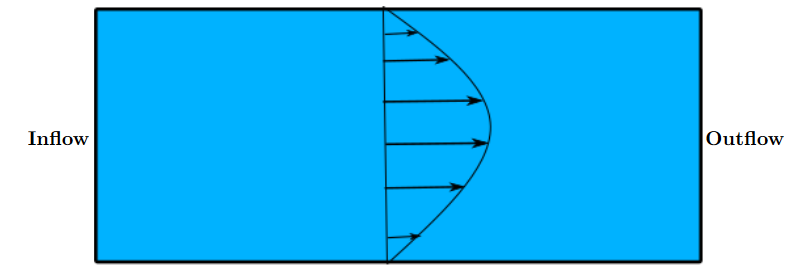

The above figure shows a cross section of fluid flow through a pipe. Let's use this in a simple thought experiment. Imagine turning a valve to start the flow of water. At first it takes some time for the water to pass all the way through the pipe. During this time, the flow rate of the fluid is unsteady. However, at some point a steady state condition will be reached, where the flow rate is constant, and the velocity profile in the fluid is no longer changing. Since time is no longer a factor, the solution of the velocity profile is going to be governed strictly by the boundary conditions of the flow. These types of problems are called elliptic, and have the following form:


$$\frac{\partial^2 u}{\partial x^2} + a \frac{\partial u^2}{\partial y^2} = 0$$


The goal of this chapter is to bring the reader's attention to different solution techniques for solving the above Laplace equation. In previous sections, we used time marching to take care of the temporal term. However, those techniques are not applicable to elliptic problems, so how do we solve for a steady state solution?

## Learning Objectives

- How to solve elliptic equations.

- Jacobi method

- Gauss-Seidel method

- Successive over relaxation

## Solving the 2D Laplace equation

Consider the following boundary value problem:


$$\frac{\partial^2 u}{\partial x^2} + a \frac{\partial^2 u}{\partial y^2} = 0$$


where the boundary conditions are as follows:

- 
$$u(y, 0) = 10, \text{ for } y\in[0, 1]$$


- 
$$u(y,1) = 0, \text{ for }y \in [0, 1]$$


- 
$$u(0, x) = u(1, x) = 0, \text{ for } x \in [0, 1]$$


- 
$$a = 1$$


To start, let's formulate a difference scheme to approximate the above partial derivatives. Here we will use the second order central difference scheme for the spatial derivatives in both $x$ and $y$. Our grid now consists of nodal points at the index $(j,i)$, where $j$ is used to denote the index for $y$ and $i$ is used to denote the index for $x$.

**Indexing grid for 2D Laplace equation**

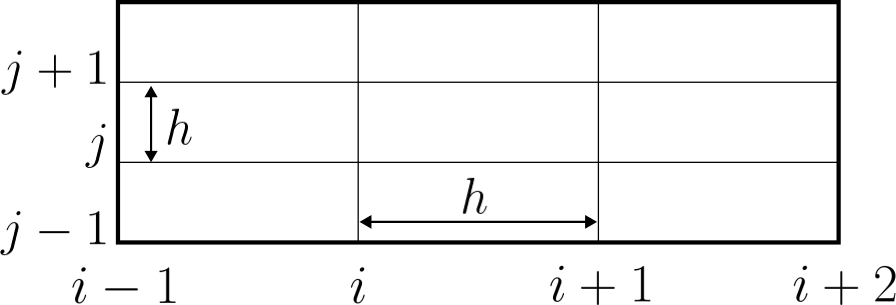

Using this notation, the approximate solution for our PDE becomes:


$$\frac{u_{j, i+1} - 2u_{j, i} + u_{j,i-1}}{\Delta x^2} + \frac{u_{j-1, i} -2u_{j,i} + u_{j+1, i}}{\Delta y^2} = 0$$


**How do we solve this equation when everything is at the same time level? **For now let's rearrange the equation and assume our grid spacing $h = \Delta x = \Delta y$:


$$u_{j,i} = \frac{1}{4} (u_{j, i+1} +  u_{j,i-1} + u_{j-1, i} + u_{j+1, i})$$


This equation tells us that the solution at $u_{j,i}$ is equal to the average of the four surrounding points. To understand how to solve this, let's look at a few different solution methods.

### Jacobi method

The Jacobi method is one of the simplest methods for solving elliptic equations. The main idea is that if we have a system of linear equations which can be put into the form $A\mathbf{x}=b$, the diagonal components of the vector $x$ are solved for by making an initial guess for the unknown values. The diagonal terms are then iteratively solved for by substituting the values obtained from the last iteration. Formally, the Jacobi method can be defined as:


$$x_i^{k+1} = \frac{1}{a_{ii}} \sum^n_{j=1} -a_{ij}x_j^{(k)} + b_i, \text{ for } i=1,2,...,n$$


Before solving the Laplace equation, let's start with a simpler linear system. Take the following system as an example:


$$5x_1 - 2x_2 + 3x_3 =  -1 \\
-3x_1 + 9x_2 + x_3 = 2 \\
2x_1 -x_2 - 7x_3 = 3$$


The above system is small enough that it could be solved by using substitution or elimination. However, if there were a million equations, it would be impractical if not impossible. So instead, the Jacobi technique can be employed. We start by solving for the diagonal terms in each equation:


$$x_1 = \frac{2}{5}x_2 - \frac{3}{5}x_3 - \frac{1}{5} \\
x_2 = \frac{3}{9}x_1 - \frac{1}{9}x_3 + \frac{2}{9} \\
x_3 = \frac{2}{7}x_1 - \frac{1}{7}x_2 - \frac{3}{7}$$


In the first equation we can guess that $x_2$ and $x_3$ are both zero, to get a value for $x_1$. We can do the same for the second and third equation as well. We then use those new values obtained for our $x$ values to then again find $x^{k+1}$ at the next iteration. If we repeat this process over and over, we get the following results:

**Solving the above linear system**

After only four iterations, the Jacobi method starts to converge to the exact answer for $x$. The Laplace equation is essentially a system of linear equations like our above example, so it can be used to solve the PDE. To do so, we would have to set up a matrix $A$ by splitting it into three parts and solving for vector $x$ as follows:

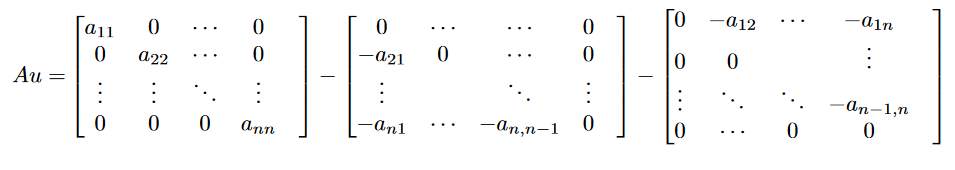

By splitting matrix $A$ into a diagonal, upper diagonal, and lower diagonal form such that $A = D - L -U$, the system looks like:


$$D\mathbf{x} = (L+U)\mathbf{x} + \mathbf{b}$$


This system can then easily be solved such that:


$$\mathbf{x} = D^{-1}(L+U)\mathbf{x} = D^{-1}\mathbf{b}$$



$$\mathbf{x^{k+1}} = D^{-1}(L+U)\mathbf{x^{k}} + D^{-1}\mathbf{b}$$


Now to find $x$, the above formulation is used until the solution begins to converge. 

### Gauss-Seidel method

The Gauss-Seidel method is based on the same formulation as the Jacobi method. However, you may have noticed that in the Jacobi method, we weren't using the most up to date information. In the first iteration, we made the initial guess of zero for all three values of $x$. However, after the first initial guess of $x_1=0$, we have an updated value for $x_1 = -0.2$. We should have used this new value to guess what $x_2$ was, instead of the old value $x_1$. The solution would have converged quicker to the exact solution. We can define the method formally as the following:


$$x_i^{k+1} = \frac{1}{a_{ii}} [\sum^n_{j=1} -a_{ij}x_j^{(k+1)} -  \sum^n_{j=i+1} -a_{ij}x_j^{(k)} + b_i], \text{ for } i=1,2,...,n$$


In matrix form:


$$\mathbf{x^{k+1}} = (D-L)^{-1}U\mathbf{x^{k}} + (D-L)^{-1}\mathbf{b}$$


### Successive Over-Relaxation

The SOR method is a variation of the Guass-Seidel, yielding faster rates of convergence. The general idea is to use a weighted average of the points in the current and previous iterations:


$$(1-w)x^k + w(GSM)^{k+1} = x^{k+1}$$


where if $0<w<1$ there is under relaxation and if $1<w<2$ there is over relaxation. The idea stems from the fact that the solution at the next iteration is a better direction to approach faster than the solution at the previous generation. So, when there is over relaxation we want to approach $k+1$ faster, and when there is under relaxation we approach $k$. 


$$x_i^{k+1} = (1-\omega)x^{(k)+ }\frac{\omega}{a_{ii}} [\sum^n_{j=1} -a_{ij}x_j^{(k+1)} -  \sum^n_{j=i+1} -a_{ij}x_j^{(k)} + b_i], \text{ for } i=1,2,...,n$$



$$\omega_{opt} = \frac{2}{1 + \frac{\pi}{n}}$$


**Stopping Criteria**

How do we know when the solution begins to converge? There are two main methods for determiningg convergence when using iterative methods.

- When the solution stops changing between iterations.

- When the error of the residual reaches a certain tolerance.

In the first case, the solution at each new iteration is compared to the solution in the previous. When they are no longer different (by some tolerance), we know the solution has converged. **Why would we perform extra iterations when the solution is no longer changing?**

In the second case, the residual error $r$ is calculated using the finite difference stencil. 


$$r(j,i) = \frac{u_{j, i+1} - 2u_{j, i} + u_{j,i-1}}{\Delta x^2} + \frac{u_{j-1, i} -2u_{j,i} + u_{j+1, i}}{\Delta y^2}$$


When the maximum value of $r < TOL$, we know the error in our solution is now bounded by the tolerance. When this condition is satisfied, we can stop iterating. 

## Comparing iterative methods

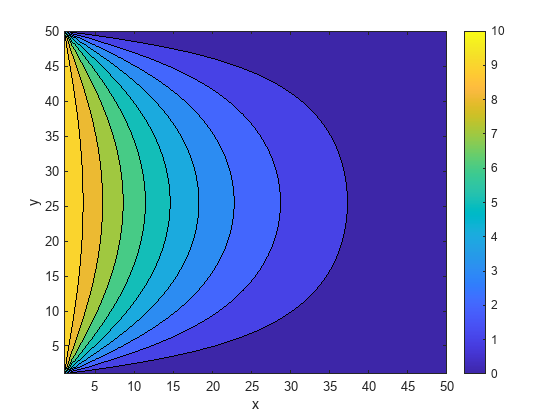

% Points in the domain
nx = 50;
ny = 50;

% Initializing solution
U_init = zeros(ny,nx);

% Boundary conditions
U_init(:,1) = 10;
U_init(:,nx) = 0;
U_init(1,:) = 0;
U_init(ny,:) = 0;

% Corners
U_init(ny,nx) = 0.5*(U_init(ny-1,nx) + U_init(ny,nx-1));
U_init(ny,1) = 0.5*(U_init(ny-1,1) + U_init(ny,2));
U_init(1,nx) = 0.5*(U_init(2,nx) + U_init(1,nx-1));
U_init(1,1) = 0.5*(U_init(1,2) + U_init(2,1));

U_original = U_init;
U_new = U_init;

% Optimization parameter
omega = 2/(1 + (pi/nx));

% Initialize error and iteration count
maxError = Inf;
iterations = 0;

% Running 3 cases, 1 for each method
numCases = 0;

% Start big loop
while numCases < 3
    while maxError > 10^-3
    
        for j=2:ny-1
            for i=2:nx-1
                % Jacobi method
                if numCases == 0
                    U_new(j,i) = 0.25*(U_init(j+1,i) + U_init(j-1,i) + U_init(j,i+1) + U_init(j,i-1));
                end

                % Gauss-Seidel method
                if numCases == 1
                    U_new(j,i) = 0.25*(U_new(j+1,i) + U_new(j-1,i) + U_new(j,i+1) + U_new(j,i-1));
                end

                % SOR
                if numCases == 2
                    U_new(j,i) = (1-omega)*U_init(j,i) +(0.25*omega)*(U_new(j+1,i) + U_new(j-1,i) + U_new(j,i+1) + U_new(j,i-1));
                end
            end
        end
        % Calculate the error
        error = U_init - U_new;
        maxError = max(max(abs(error)));
        
        % Set U for next iteration
        U_init = U_new;
    
        % Keep track of each iteration
        iterations = iterations + 1;
    end
    caseIterations(numCases+1) = iterations;
    numCases = numCases + 1;

    U_solution = U_new;

    % Reset conditions
    U_init = U_original;
    U_new = U_init;
    maxError = 1;
    iterations = 0;
end

% Plot the solution
figure
contourf(U_solution)
xlabel("x")
ylabel("y")
colorbar

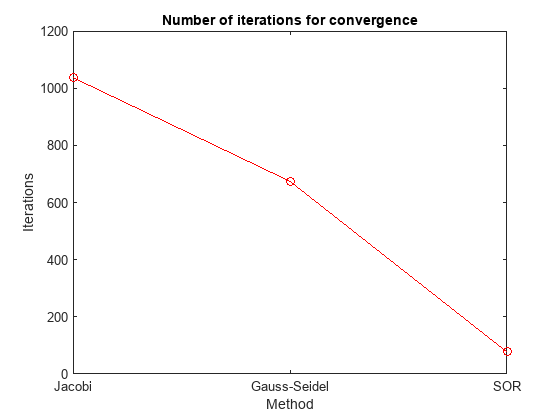

% Compare solutions across the different methods
figure
labels = {'Jacobi' 'Gauss-Seidel' 'SOR'};
plot(caseIterations,'ro-')
set(gca, 'XTick',1:3,'XTickLabel',labels)
xlabel("Method")
ylabel("Iterations")
title("Number of iterations for convergence")

## **Direct Solve**

It turns out, there is more to life than iterative methods. In general, iterative methods are used out of necessity, convenience,  or efficiency. They are usually used when the matrix becomes sufficiently large and can no longer fit in memory. Iterative methods generally require less memory, but can fail to converge if the method is not well-built or robust. Luckily for us,  MATLAB has highly efficient direct solvers. To utilize them, we must first build the coefficient matrix. 

**Example grid stencil**

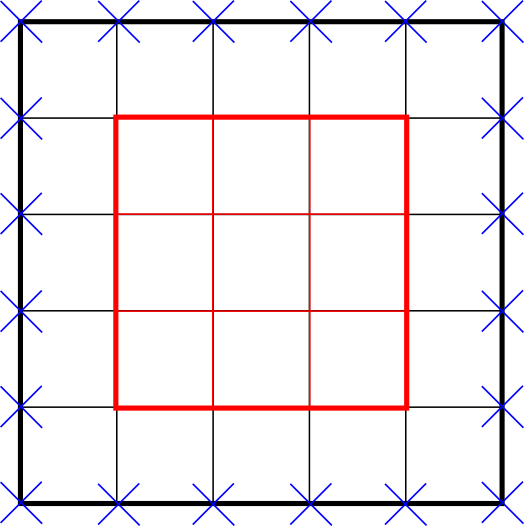

In the above image, the red grid denotes the stencil that exists inside the domain. The black grid which includes blue crosses denotes the points along the boundary. To perform a direct solve, the matrix must be of the form $A\mathbf{x} = \mathbf{b}$, where $A$ is the coefficient matrix, $\mathbf{x}$ is the solution, and $\mathbf{b}$ is the right hand side which includes the boundary conditions. Remember that the central difference scheme is:


$$\frac{u_{j, i+1} - 2u_{j, i} + u_{j,i-1}}{\Delta x^2} + \frac{u_{j-1, i} -2u_{j,i} + u_{j+1, i}}{\Delta y^2} = 0$$


The Laplace equation in matrix form follows the following tridiagonal block matrix.

**Tridiagonal block matrix**

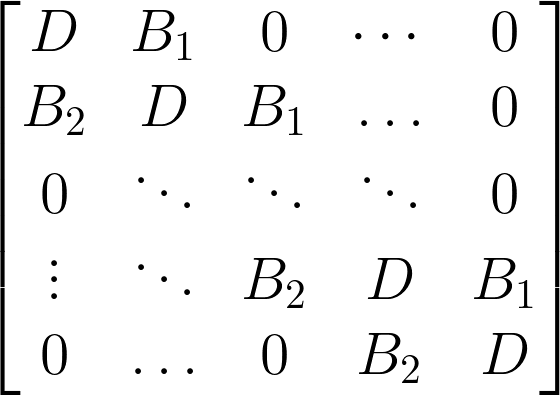

Here, $D$ is the traditional stencil containing coefficients for $-4u_{j,i}$, $u_{j+1,i}$, $u_{j-1,i}$ with $B_1$ and $B_2$ containing the coefficients for $u_{j,i+1}$ and $u_{j,i-1}$ , respectively. You may be wondering why the matrix is formed this way. It is because we are now solving a PDE on a two-dimensional stencil and $\mathbf{x}$ must contain all points in that stencil. Using a stencil of this manner, $\mathbf{x}$ is of the following form:

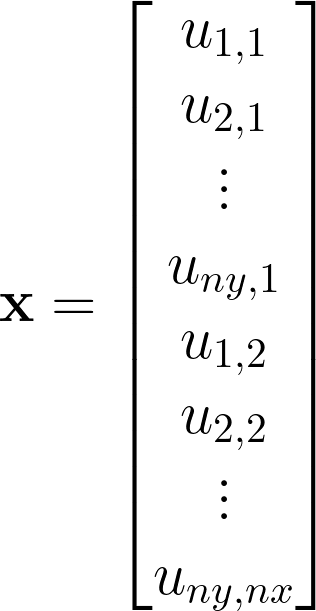

The easiest way to form this matrix is to use the Kronecker delta tensor product. If $A$ is a $m\times n$ matrix and $B$ is a $p \times q$ matrix, then the Kronecker product is:

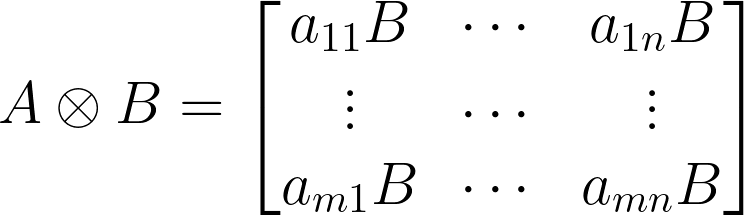

Using this product, the $D$ and $B$ matrices can first be formed and then put into tridiagonal form.

% Build the coefficient matrix
nx = 5;   % Full grid
n = nx-2; % Internal grid

e = ones(n,1);
T_D = spdiags([e -4*e e],-1:1,n,n); % Diagonal matrix
T_B = spdiags([e 0*e e],-1:1,n,n);  % B matrix

% Kronecker delta product
D =  kron(speye(n),T_D); 
B = kron(T_B,speye(n));

A = D + B;
full(A)

ans =     -4     1     0     1     0     0     0     0     0
     1    -4     1     0     1     0     0     0     0
     0     1    -4     0     0     1     0     0     0
     1     0     0    -4     1     0     1     0     0
     0     1     0     1    -4     1     0     1     0
     0     0     1     0     1    -4     0     0     1
     0     0     0     1     0     0    -4     1     0
     0     0     0     0     1     0     1    -4     1
     0     0     0     0     0     1     0     1    -4


Now that the internal matrix has been formed,  we are only missing the right hand side. This will be explained in the second exercise. Once the right hand side is formed, a direct solve can be performed in MATLAB using:

##  Exercise 1

Solve the Laplace equation with the following boundary conditions.


$$\frac{\partial^2 u}{\partial x^2} + a \frac{\partial^2 u}{\partial y^2} = 0$$


- 
$$u(y, 0) = 10, \text{ for } y\in[0, 1]$$


- 
$$u(y,1) = 5, \text{ for }y \in [0, 1]$$


- 
$$u(0, x) = 4, \text{ for } x \in [0, 1]$$


- 
$$u(1, x) = 1, \text{ for } x \in [0, 1]$$


- 
$$a = 1$$


open("exercise/laplace_ex1.m");

**Answer the following questions:**

- How well do the iterative methods compare to one another?

- Is there a more optimal weighting parameter than the one given in the code?

- How does changing the stopping criteria affect the solution? Does the number of iterations change between stopping criteria 1 and 2?

## ** Exercise 2**

Solve the previous problem again, but this time use a direct solve. Compare the solutions against each other.

% open("exercise/laplace_ex2.m");

 **Hint: **The right hand side 

## ** Exercise 3**

Solve the following Laplace equation for a rectangular domain using a direct solve. In this case the length of the domain is $L=2$ and the height of the domain $H=1$.


$$\frac{\partial^2 u}{\partial x^2} + a \frac{\partial^2 u}{\partial y^2} = 0$$


- 
$$u(y, 0) = 10, \text{ for } y\in[0, 1]$$


- 
$$u(y,1) = 5, \text{ for }y \in [0, 1]$$


- 
$$u(0, x) = 4, \text{ for } x \in [0, 2]$$


- 
$$u(1, x) = 1, \text{ for } x \in [0, 2]$$


- 
$$a = 1$$


% open("exercise/laplace_ex3.m");

 **Hint: **You will need to construct two specific $T$ matrices, one for $x$ and one for $y$. 

**Next section:**

This concludes the chapter on finite difference methods. The next course module is focused on building a computational fluid dynamics solver for single phase flow. In this chapter, the full Navier-Stokes equations (NSE) are solved using the finite volume method. The NSE are a set of non-linear partial differential equations comprised of parabolic, hyperbolic and elliptic parts. Now that we have established a basis for solving PDEs, the following code opens up the course module for learning CFD.

% open("../NavierStokes/flowSolver_teachingModule.mlx")